# Digital Signal Processing | Lab 02

## Eperiment 3

Question A

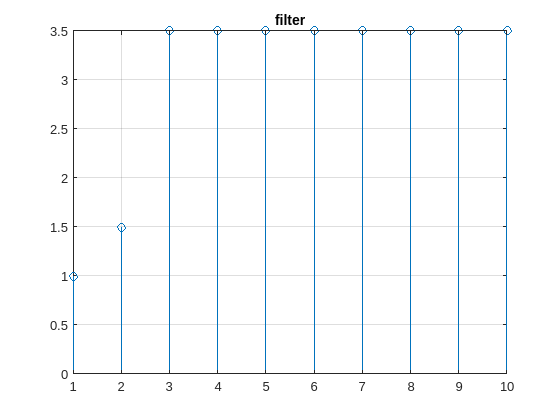

a = [1, 0.5, 2];
b = [1];
x = ones(1, 10);

y = filter(a, b, x);

figure;
stem(y);
title('filter');

The expected steady-state value = 3.5 (last value).

Question B

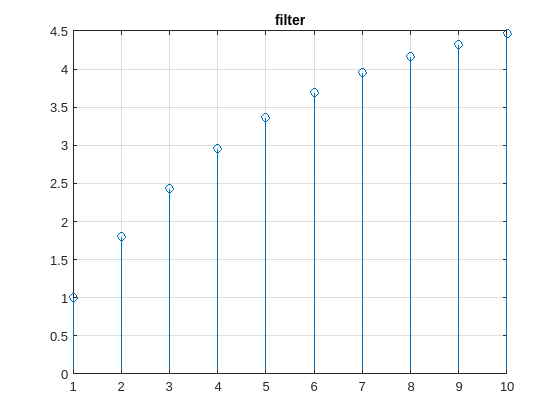

a = [1 -0.8];
b = [1];
x = ones(1,10);
y = filter(b, a, x);
figure; stem(y); title('filter');

Question C

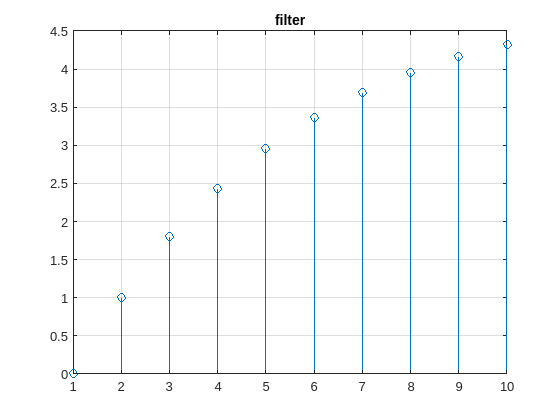

a = [1, -0.8];
b = [1];
x = ones(1, 10);
xshift = [0, x(1:end-1)];
y = filter(b, a, xshift);
figure;
stem(y);
title('filter');

The signal in C is delayed by 1 unit from the signal in B.

Question D

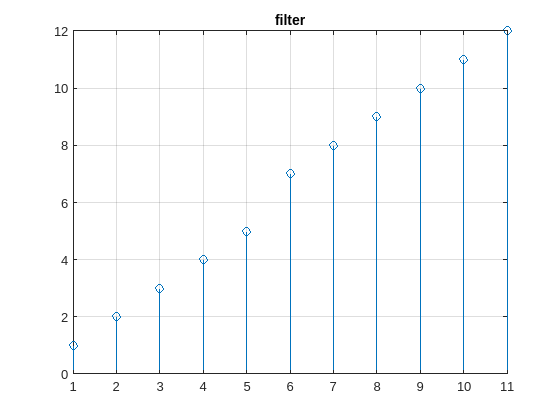

a = [1, -1];
b = [1];
x = [1 1 1 1 1 2 1 1 1 1 1];
y = filter(b, a, x);
figure;
stem(y);
title('filter');

### Average moving filter

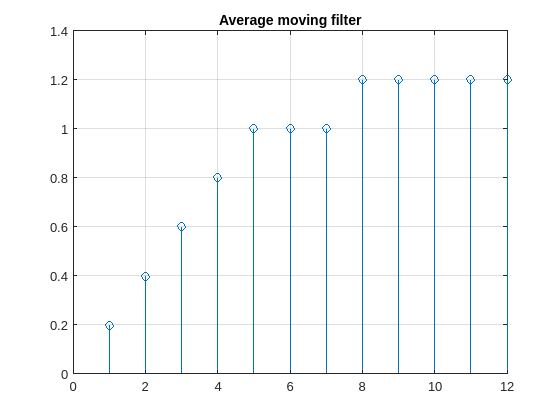

b = ones(1, 5) ;
b = b / length(b);

x=[1 1 1 1 1 1 1 2 1 1 1 1 ];
y = filter(b,1,x);
figure;
stem(y);
title('Average moving filter');

Averages the values of the last 5 samples.

## Exercises

1.

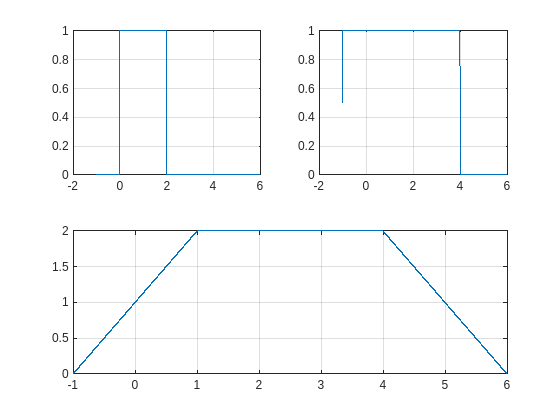

u = @(x) heaviside(x);
r = @(a, b, i) a <= i & i <= b;

fs = 1000;

n = -1:1/fs:6;

x1 = u(n) - u(n-2);
x2 = u(n + 1) - u(n-4);

x3 = conv(x1(r(0, 2, n)), x2(r(-1, 4, n))) / fs;

figure;
subplot(2,2,1); plot(n, x1);
subplot(2,2,2); plot(n, x2);
subplot(2,1,2); plot(n, x3);

2.

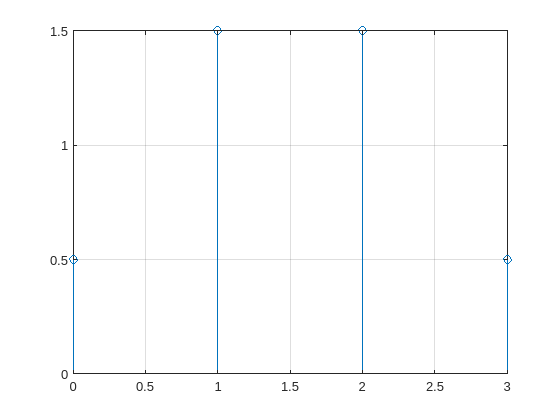

n = 0:3;

x = u(n) - u(n-2);
h = zeros(1, length(n));
h(n==0 | n==1) = 1;

y = conv(x(r(0, 2, n)), h(r(0, 1, n)));
figure; stem(n, y);

3.

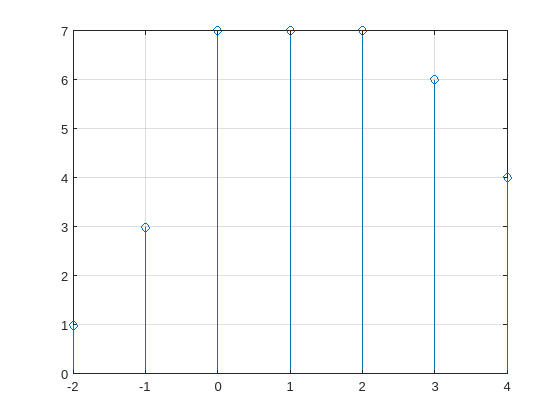

x1 = [1 2 4];
h1 = [1 1 1 1 1];
y1 = conv(x1, h1);
figure; stem(-2:4 ,y1);

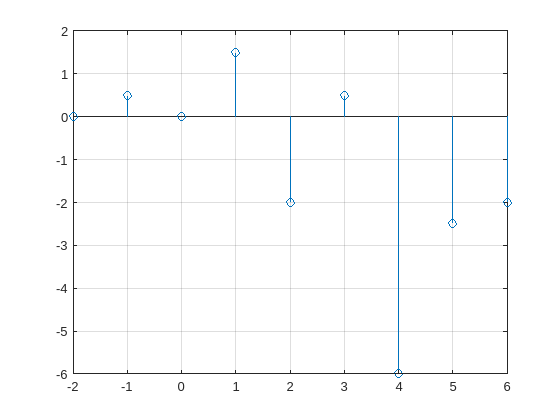

x2 = [0 1 -2 3 -4];
h2 = [0.5 1 2 1 0.5];
y2 = conv(x2, h2);
figure; stem(-2:6, y2);

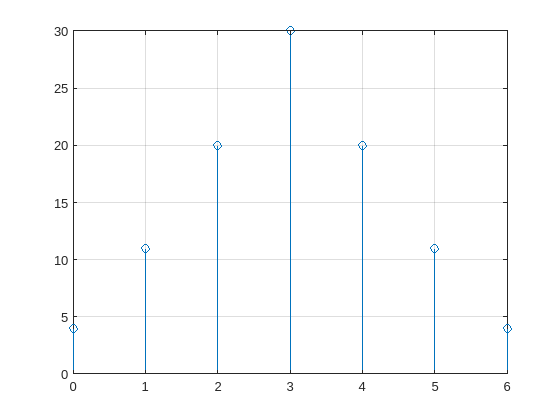

x3 = [1 2 3 4];
h3 = [4 3 2 1];
y3 = conv(x3, h3);
figure; stem(0:6, y3);

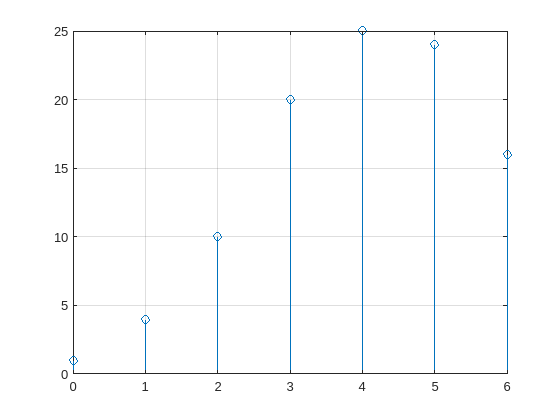


x4 = [1 2 3 4];
h4 = [1 2 3 4];
y4 = conv(x4, h4);
figure; stem(0:6, y4);